% Parameters
fs = 4100;  % Sampling frequency (adjusted based on the audio file)
bufferSize = 4096;  % Size of buffer for segmenting the audio
cutoffFreq = 5000;  % Cutoff frequency for low-pass filter (adjust based on expected bird sounds)
minFreq = 100;  % Minimum expected frequency to avoid identifying noise
maxFreq = 5000; % Maximum expected frequency

% Bird Database [BirdName, MinFundamentalFreq, MaxFundamentalFreq]
birdDB = {'Sparrow', 2000, 10000; ...
          'Crow', 2000, 5000; ...
          'Nightingale', 1000, 4000; ...
          'Pigeon', 1000, 4500; ...
          'Owl', 2000, 6000; ...
          'Hummingbird', 3000, 3500; ...
          'Parrot', 300, 1000;...
          'Peacock',100,600}; 

% Load the audio file with bird sounds
[audioData, fs] = audioread('4mix.wav');  % Replace with your actual file path

% Convert stereo to mono if needed
if size(audioData, 2) > 1
    audioData = mean(audioData, 2);
end

% Number of samples in the audio file
numSamples = length(audioData);

% Apply a low-pass filter
lpFilter = designfilt('lowpassiir','FilterOrder',8, 'HalfPowerFrequency',cutoffFreq/(fs/2));
audioData = filter(lpFilter, audioData);

% Store bird durations
birdDurations = containers.Map;
timeStamps = [];  % Store time stamps for plotting
fundamentalFreqs = [];  % Store fundamental frequencies for plotting
birdLabels = {};  % Store labels for each segment

% Processing each segment of the audio file
disp('Processing the audio file...');

Processing the audio file...


for idx = 1:bufferSize:(numSamples-bufferSize)
    % Extract segment
    segment = audioData(idx:idx+bufferSize-1);
    
    % Skip silent segments
    if max(abs(segment)) < 1e-4
        continue;
    end
    
    % Apply Hamming window
    windowedSegment = segment .* hamming(bufferSize);
    
    % FFT to find fundamental frequency
    N = length(windowedSegment);
    Y = fft(windowedSegment);
    P2 = abs(Y/N);
    P1 = P2(1:N/2+1);
    P1(2:end-1) = 2*P1(2:end-1);
    f = fs*(0:(N/2))/N;
    
    % Limit to expected frequency range
    validFreqRange = (f >= minFreq) & (f <= maxFreq);
    P1 = P1(validFreqRange);
    f = f(validFreqRange);
    
    % Find peak in FFT
    [~, peakIdx] = max(P1);
    fundamentalFreq = f(peakIdx);
    
    % Identify bird based on fundamental frequency
    birdIdentified = 'Unknown';
    for i = 1:size(birdDB, 1)
        if fundamentalFreq >= birdDB{i, 2} && fundamentalFreq <= birdDB{i, 3}
            birdIdentified = birdDB{i, 1};
            break;
        end
    end
    
    % Update bird duration if identified
    if ~strcmp(birdIdentified, 'Unknown')
        if isKey(birdDurations, birdIdentified)
            birdDurations(birdIdentified) = birdDurations(birdIdentified) + (bufferSize/fs);
        else
            birdDurations(birdIdentified) = (bufferSize/fs);
        end
        
        % Store data for plotting
        timeStamps = [timeStamps, idx/fs];  % Convert index to time in seconds
        fundamentalFreqs = [fundamentalFreqs, fundamentalFreq];
        birdLabels = [birdLabels, {birdIdentified}];
    end
end

% Display the bird durations
disp('Birds identified and their durations:');

Birds identified and their durations:


birdKeys = keys(birdDurations);
for i = 1:length(birdKeys)
    fprintf('%s: %.2f seconds\n', birdKeys{i}, birdDurations(birdKeys{i}));
end

Nightingale: 5.76 seconds
Parrot: 1.39 seconds
Peacock: 7.52 seconds
Sparrow: 5.39 seconds



disp('Processing completed.');

Processing completed.


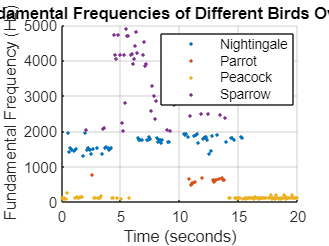


% Plot the fundamental frequencies
figure;
hold on;
colors = lines(length(birdKeys));  % Generate a colormap
legendEntries = {};

% Plot each bird's fundamental frequency with a different color
for i = 1:length(birdKeys)
    birdName = birdKeys{i};
    birdMask = strcmp(birdLabels, birdName);
    plot(timeStamps(birdMask), fundamentalFreqs(birdMask), '.', 'Color', colors(i, :), 'DisplayName', birdName);
    legendEntries{end+1} = birdName;  % Add to legend
end

% Customize plot
title('Fundamental Frequencies of Different Birds Over Time');
xlabel('Time (seconds)');
ylabel('Fundamental Frequency (Hz)');
legend(legendEntries, 'Location', 'best');
grid on;
hold off;